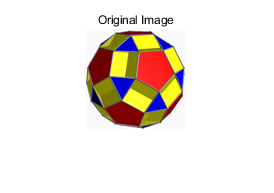

I = im2double(imread('block.png'));
imshow(I);
title('Original Image');

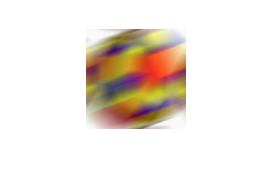

LEN = 40;
THETA = 20;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(I, PSF, 'conv', 'circular');
figure, imshow(blurred)

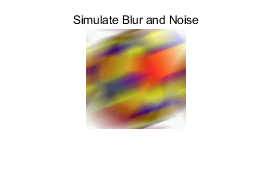

noise_mean = 0;
noise_var = 0.0001;
blurred_noisy = imnoise(blurred, 'gaussian', ...
                        noise_mean, noise_var);
figure, imshow(blurred_noisy)
title('Simulate Blur and Noise')

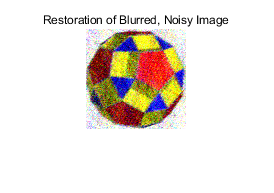

estimated_nsr = noise_var / var(I(:));
wnr3 = deconvwnr(blurred_noisy, PSF, estimated_nsr);
figure, imshow(wnr3)
title('Restoration of Blurred, Noisy Image');